# EDUCAT database visualization

TIP: when getting new data or new connection --> right click on white space and choose " clear all Output" 

clear all Output
clc
close all
username = "analyst";
userInput = ' password: ';
password = input(userInput,'s');

import classes.measurement
import classes.instrument
import classes.data
m = measurement(username,password);
clc;
clear password userInput username;

 
m.list

## Declaration of measurement

id= 58;
if( size(find(m.list.id == id),1)==1 && m.list.count(find(m.list.id == id,1)) > 2)
    disp('ID exist, running...')
    m=m.set_measurement_ID(id);
    m = m.declaration();
    % ******* get data ********
    m = m.get_dataset_DB();
    disp("done")
elseif m.list.count(find(m.list.id == id,1)) < 2
    disp("measurement contains no data")
else
    disp("ID does not exist in database")
end

ID exist, running...


done


%test = m.exportData();



## Plot all measurement information

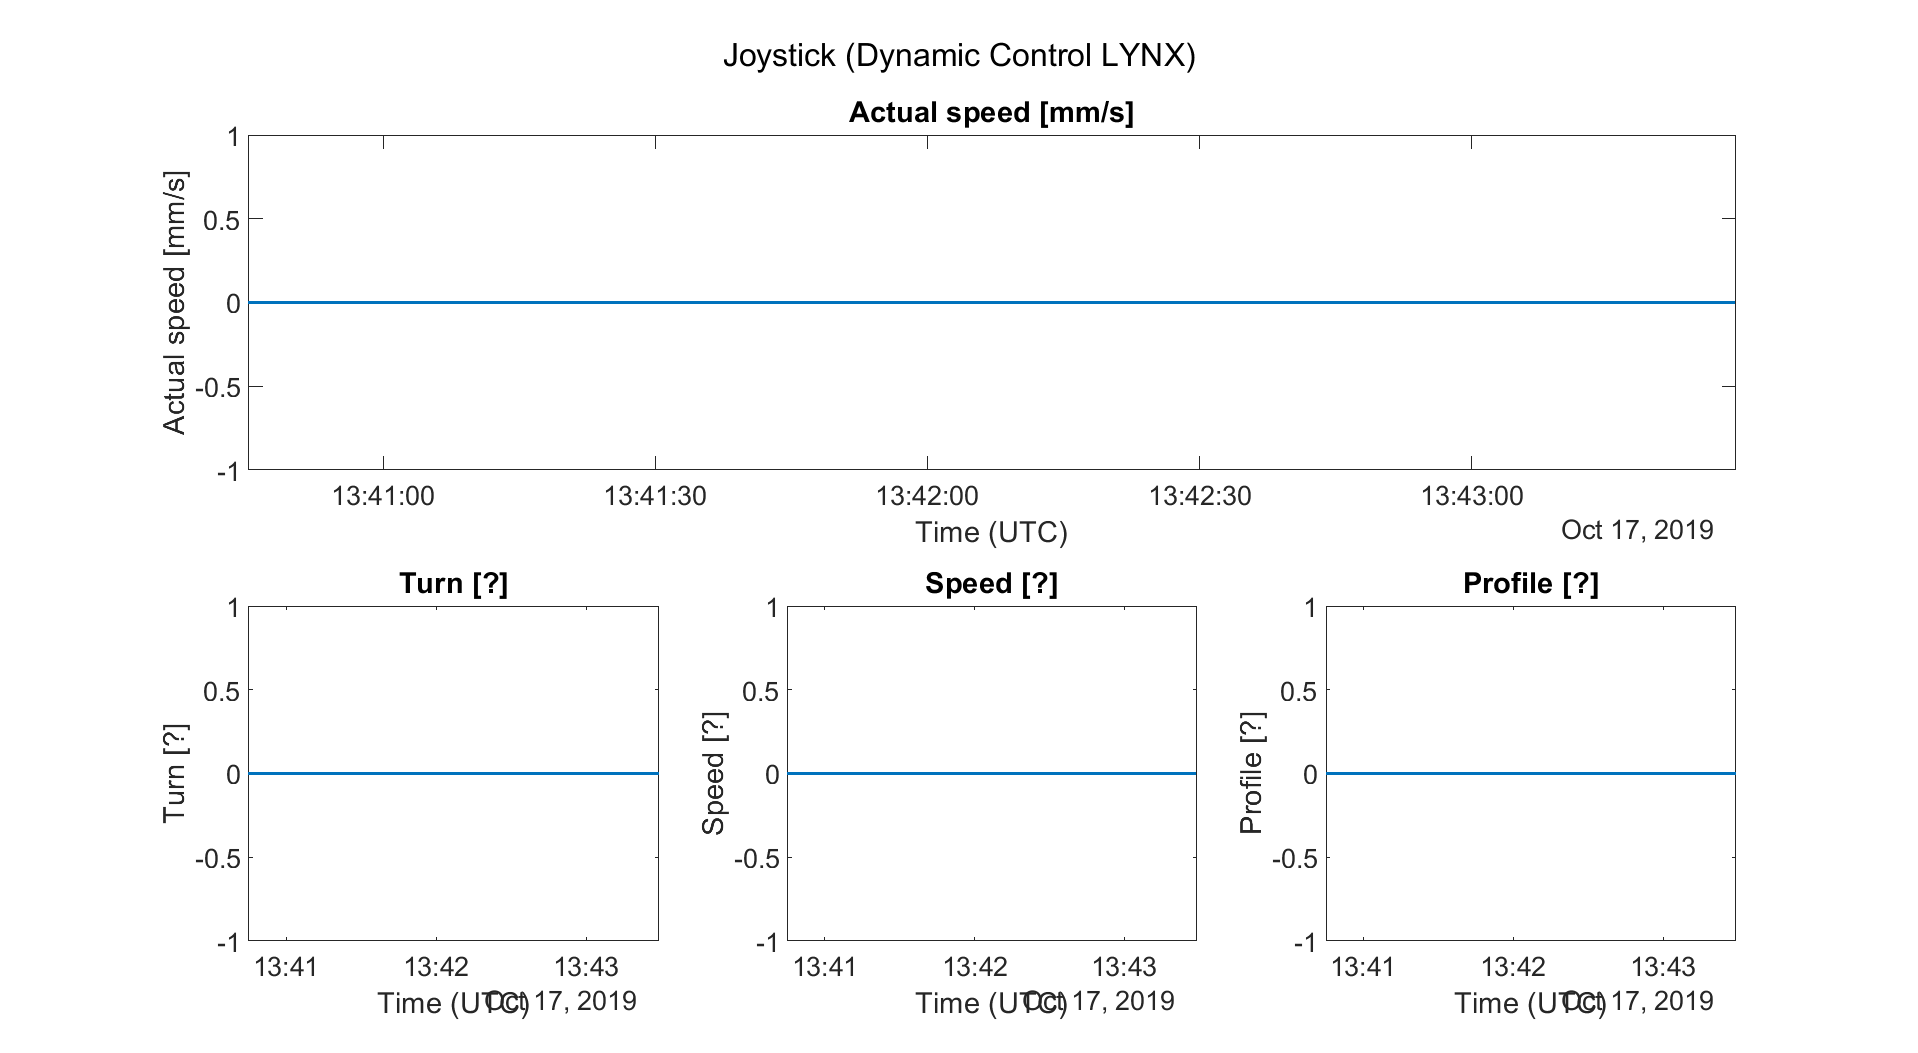

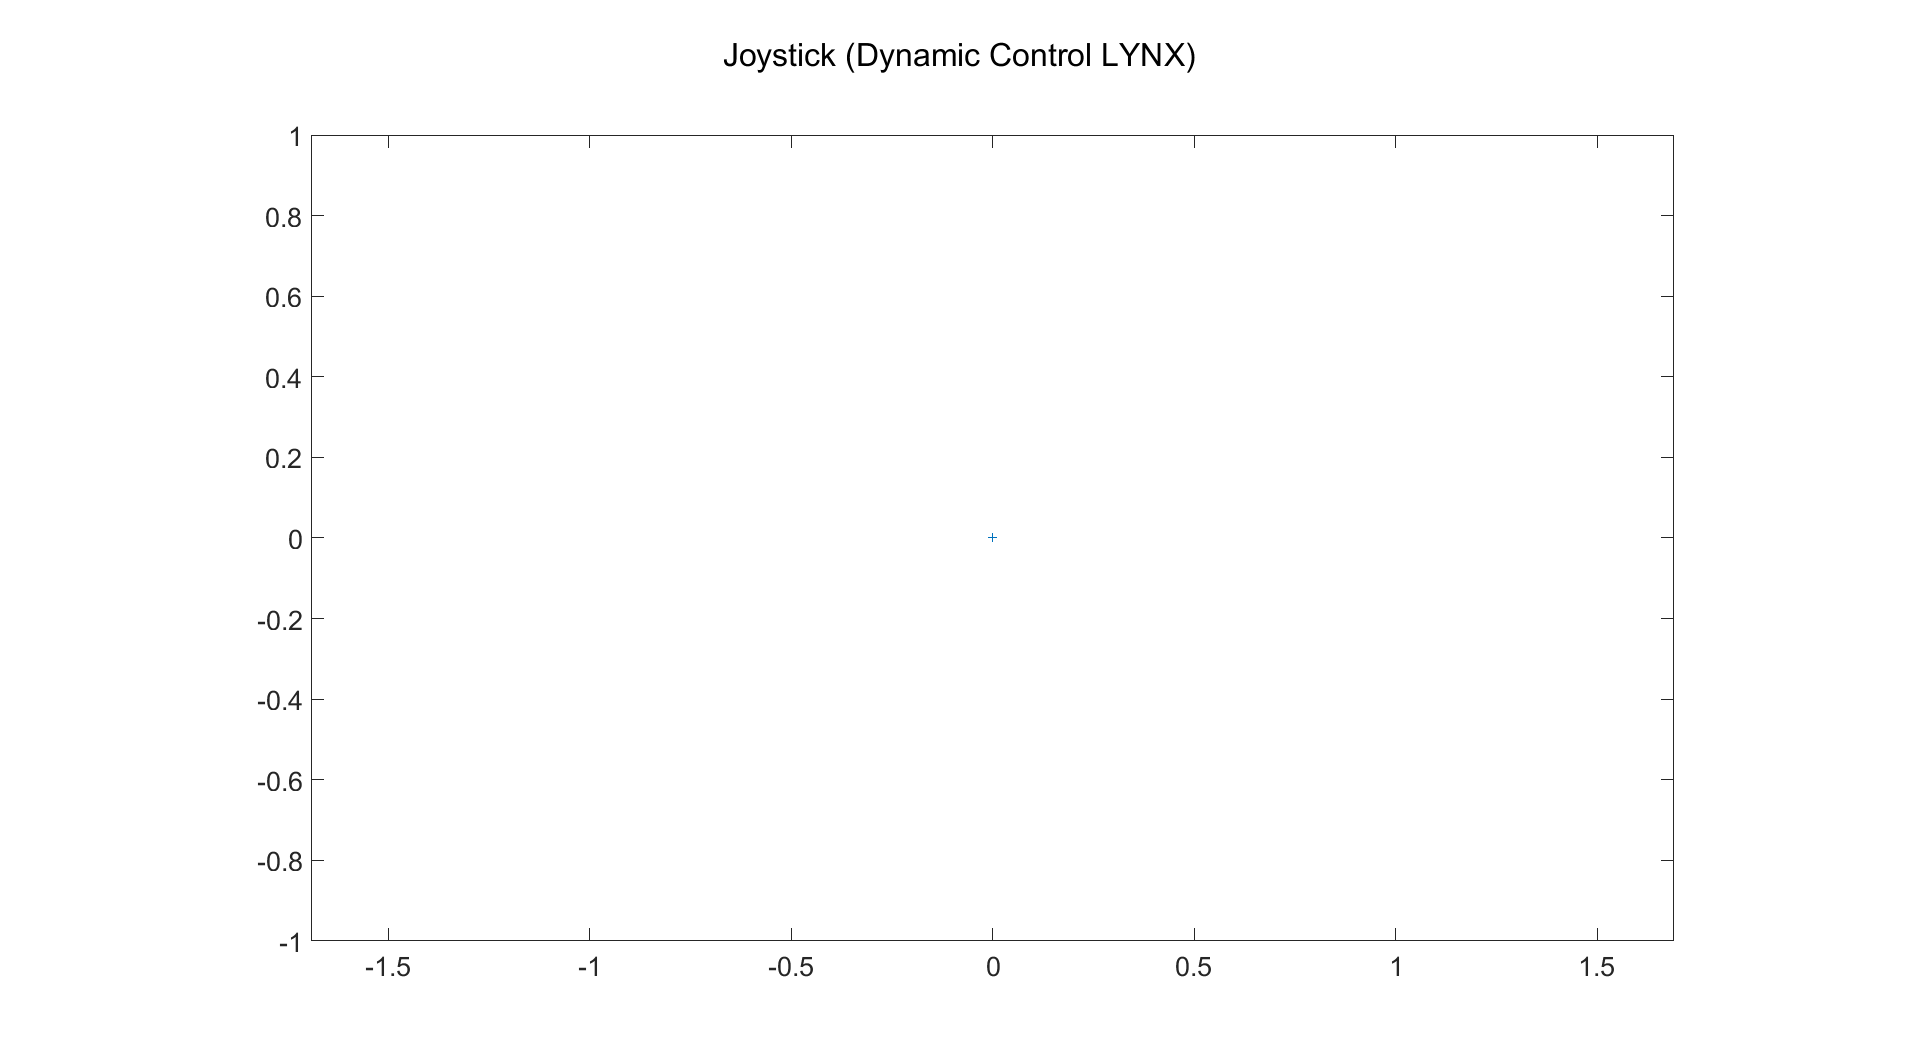

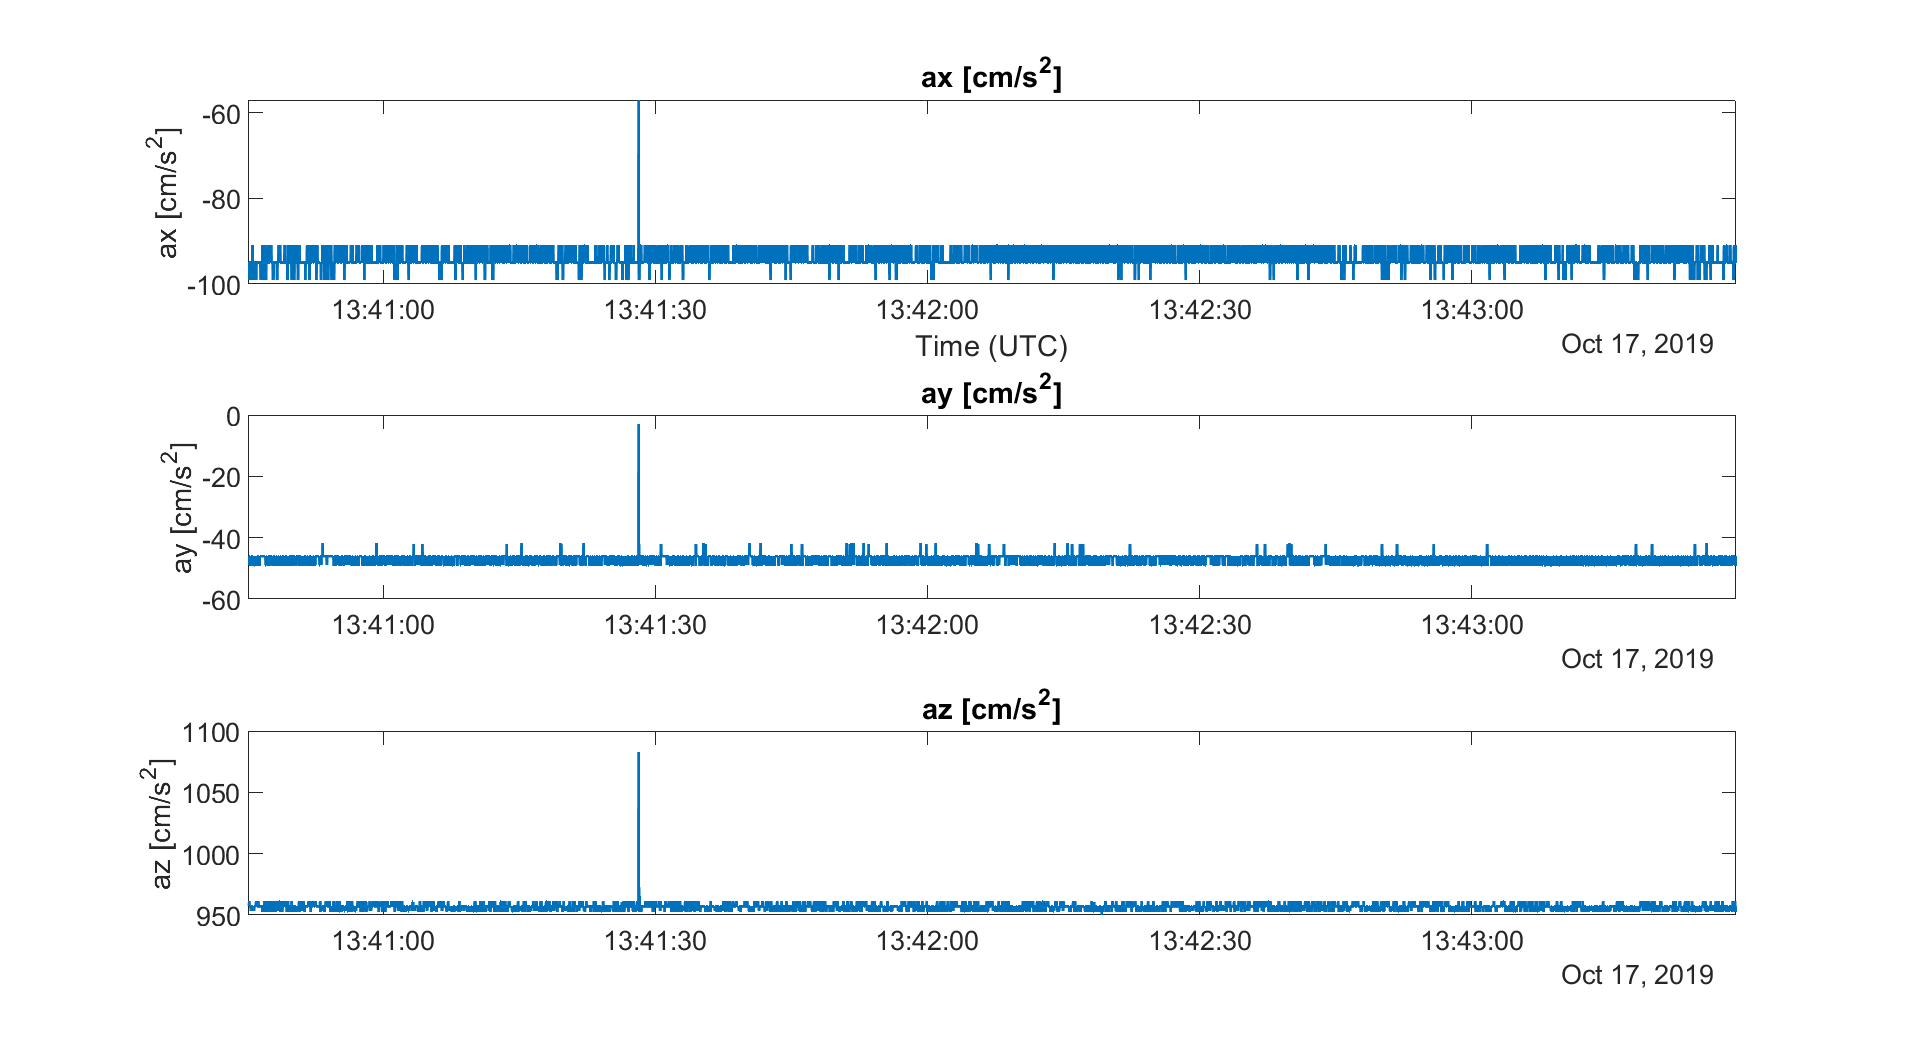

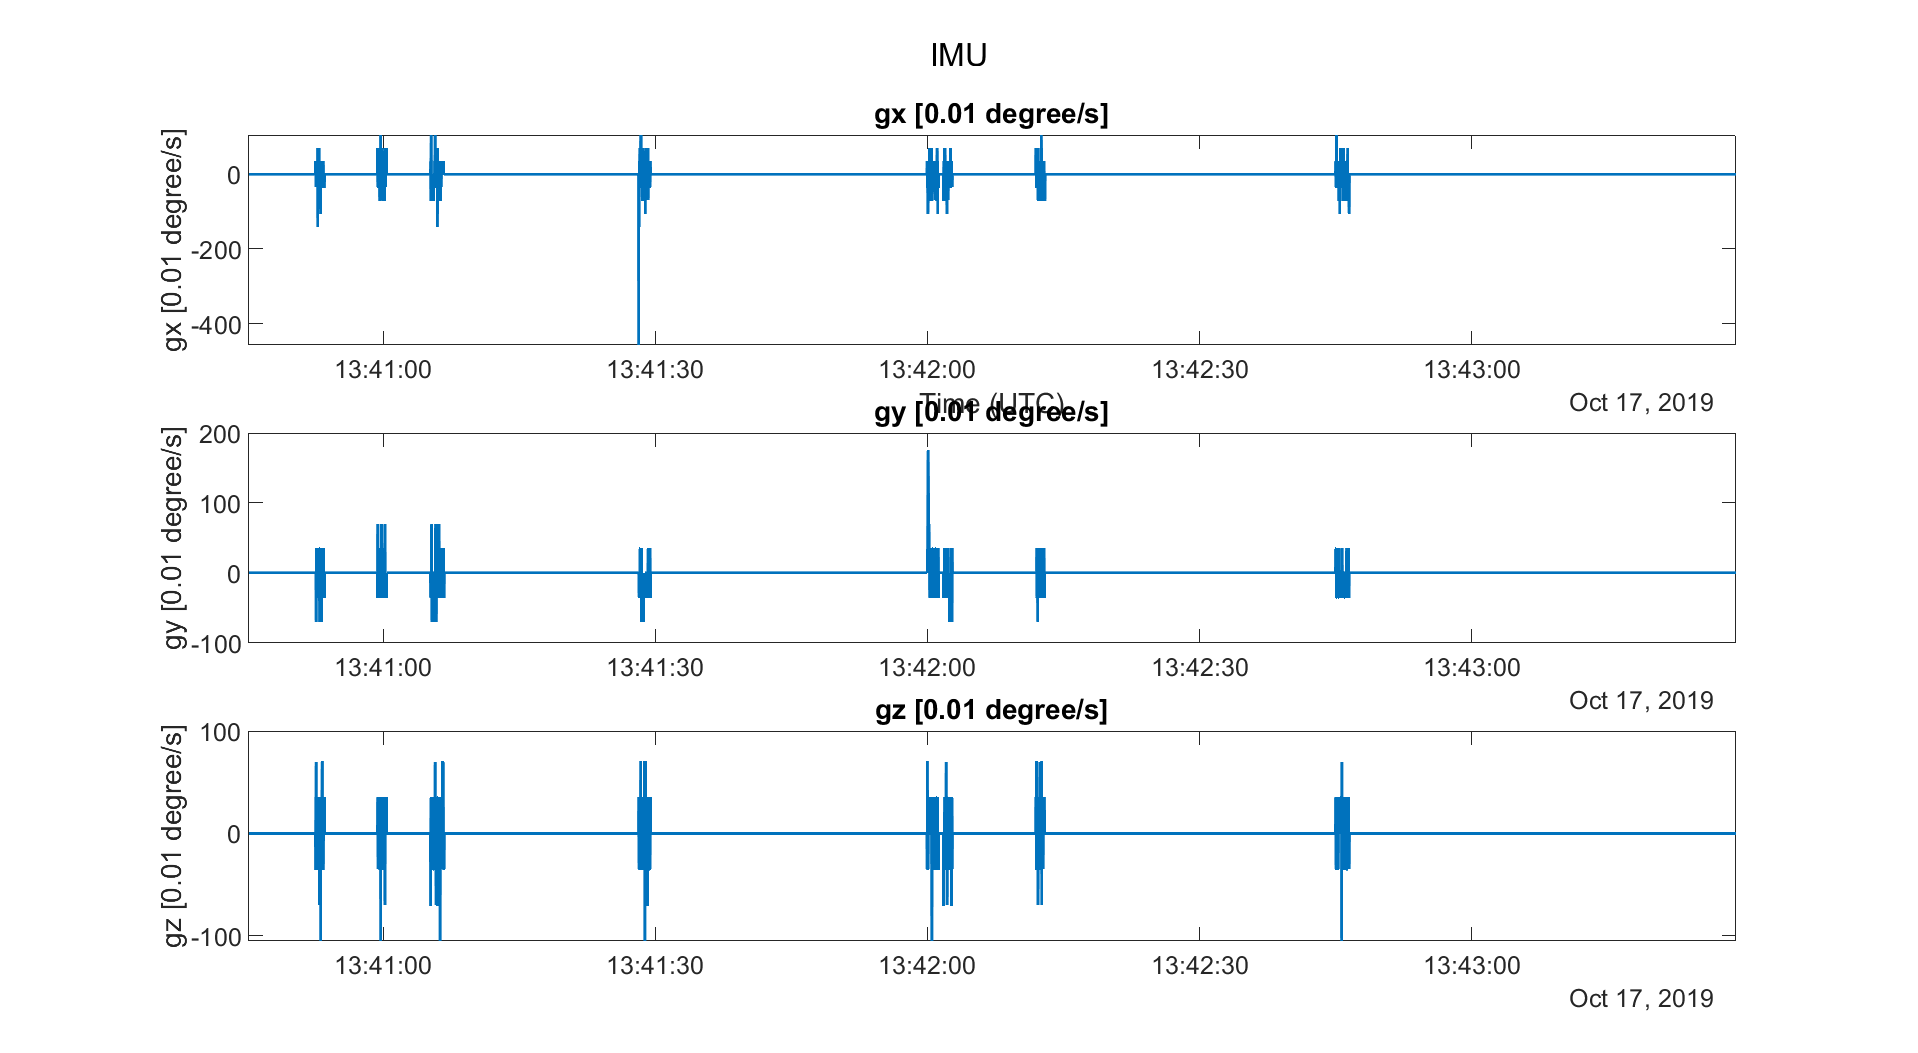

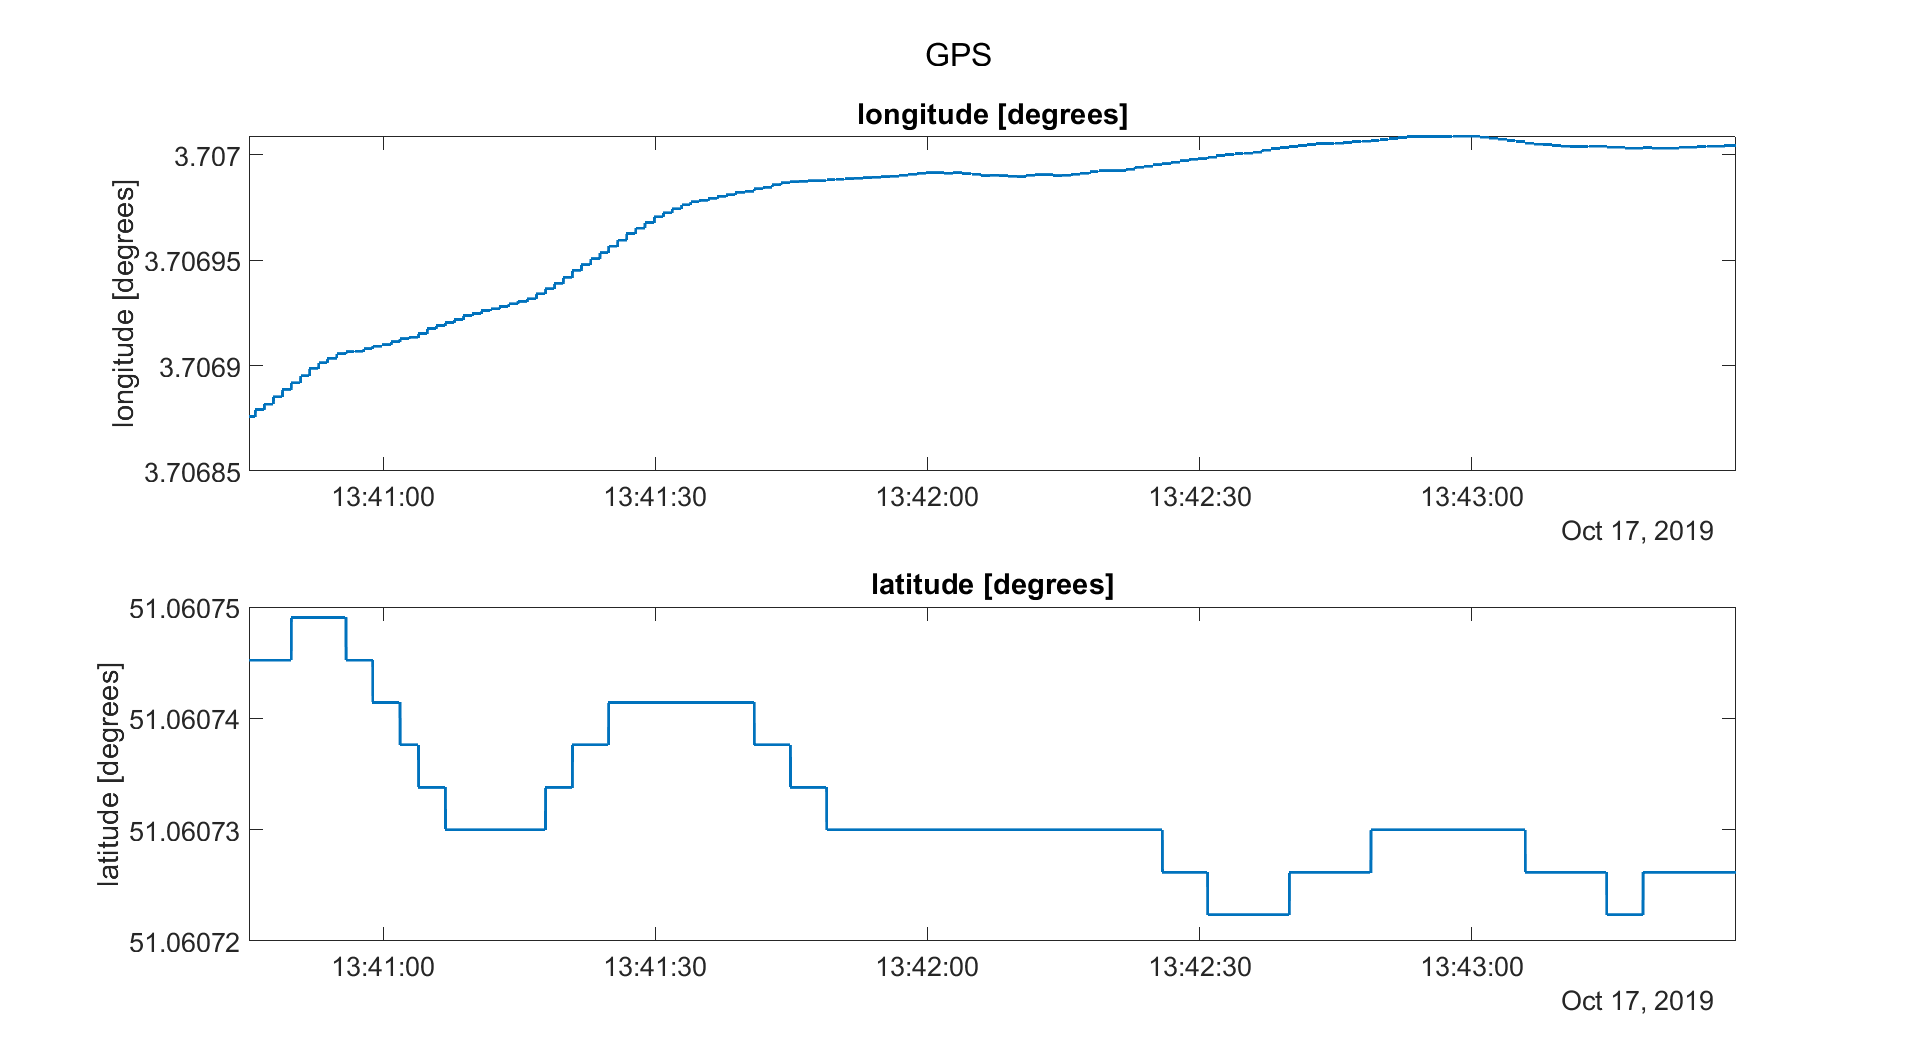

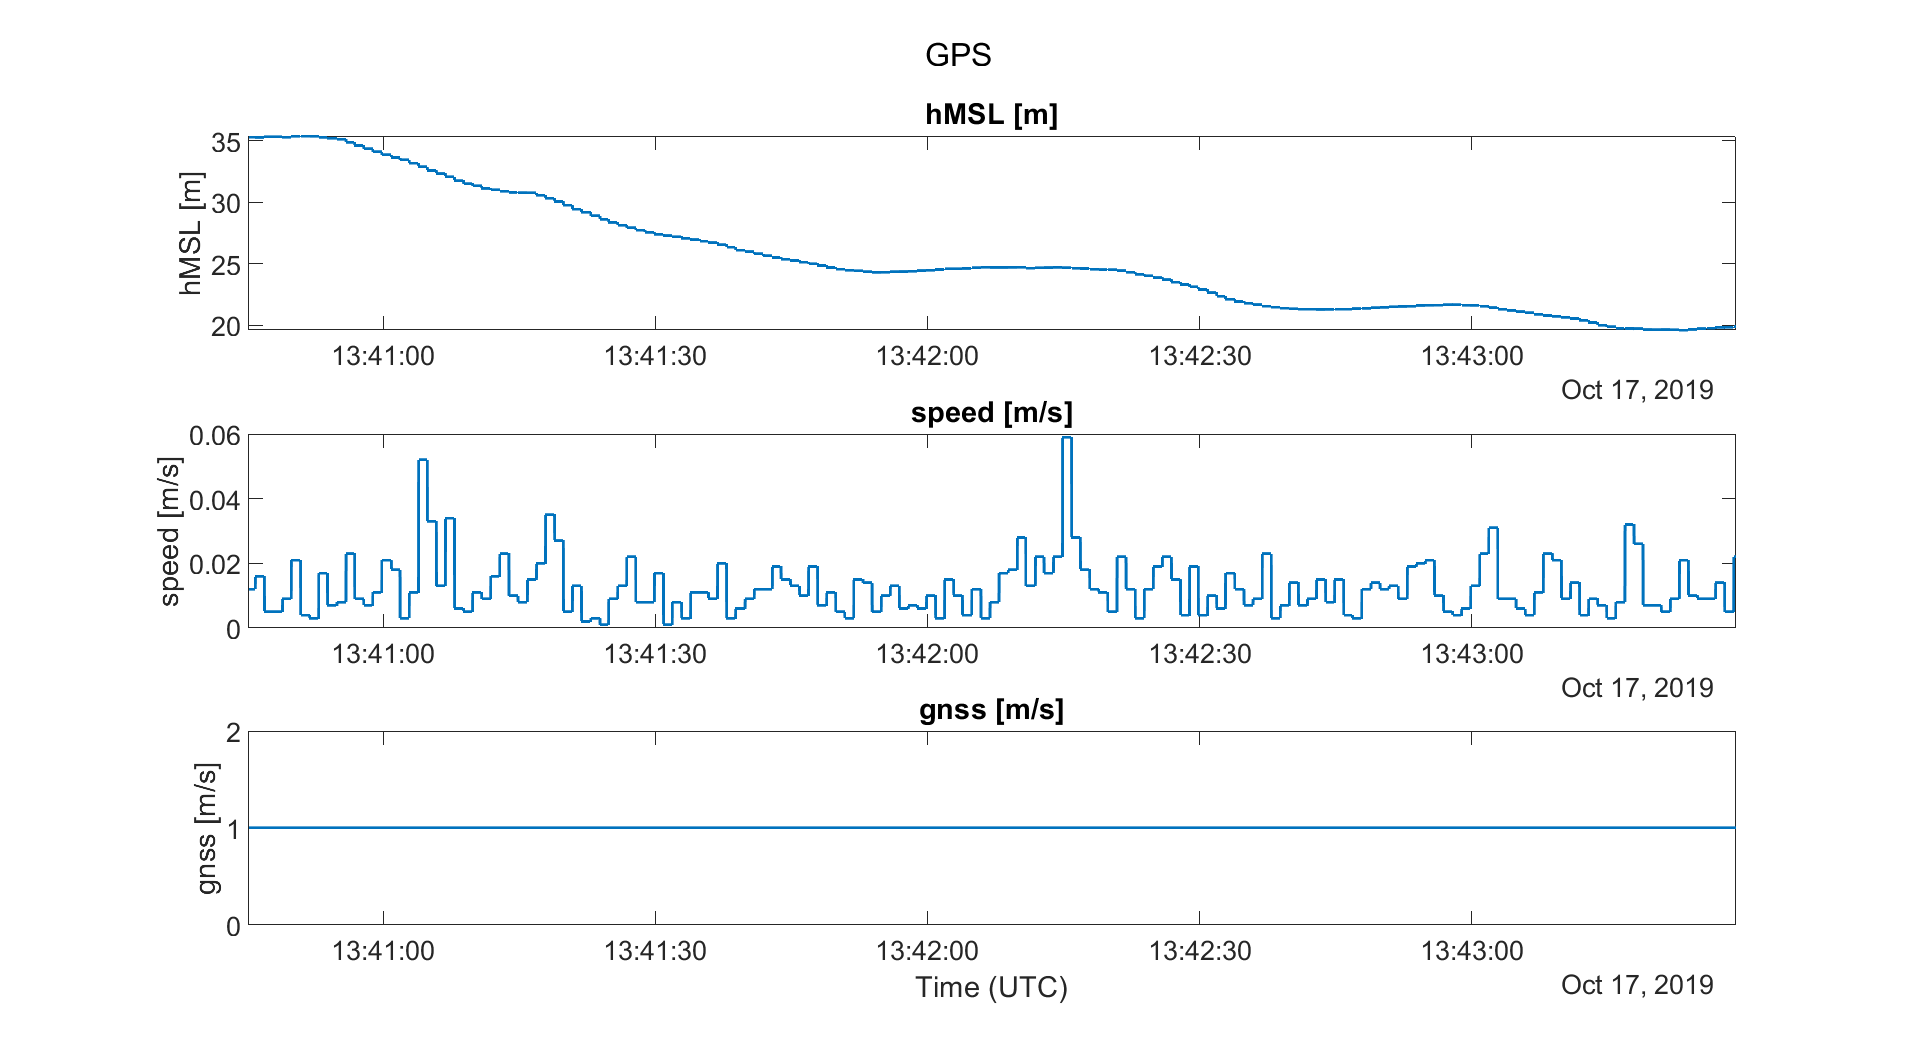

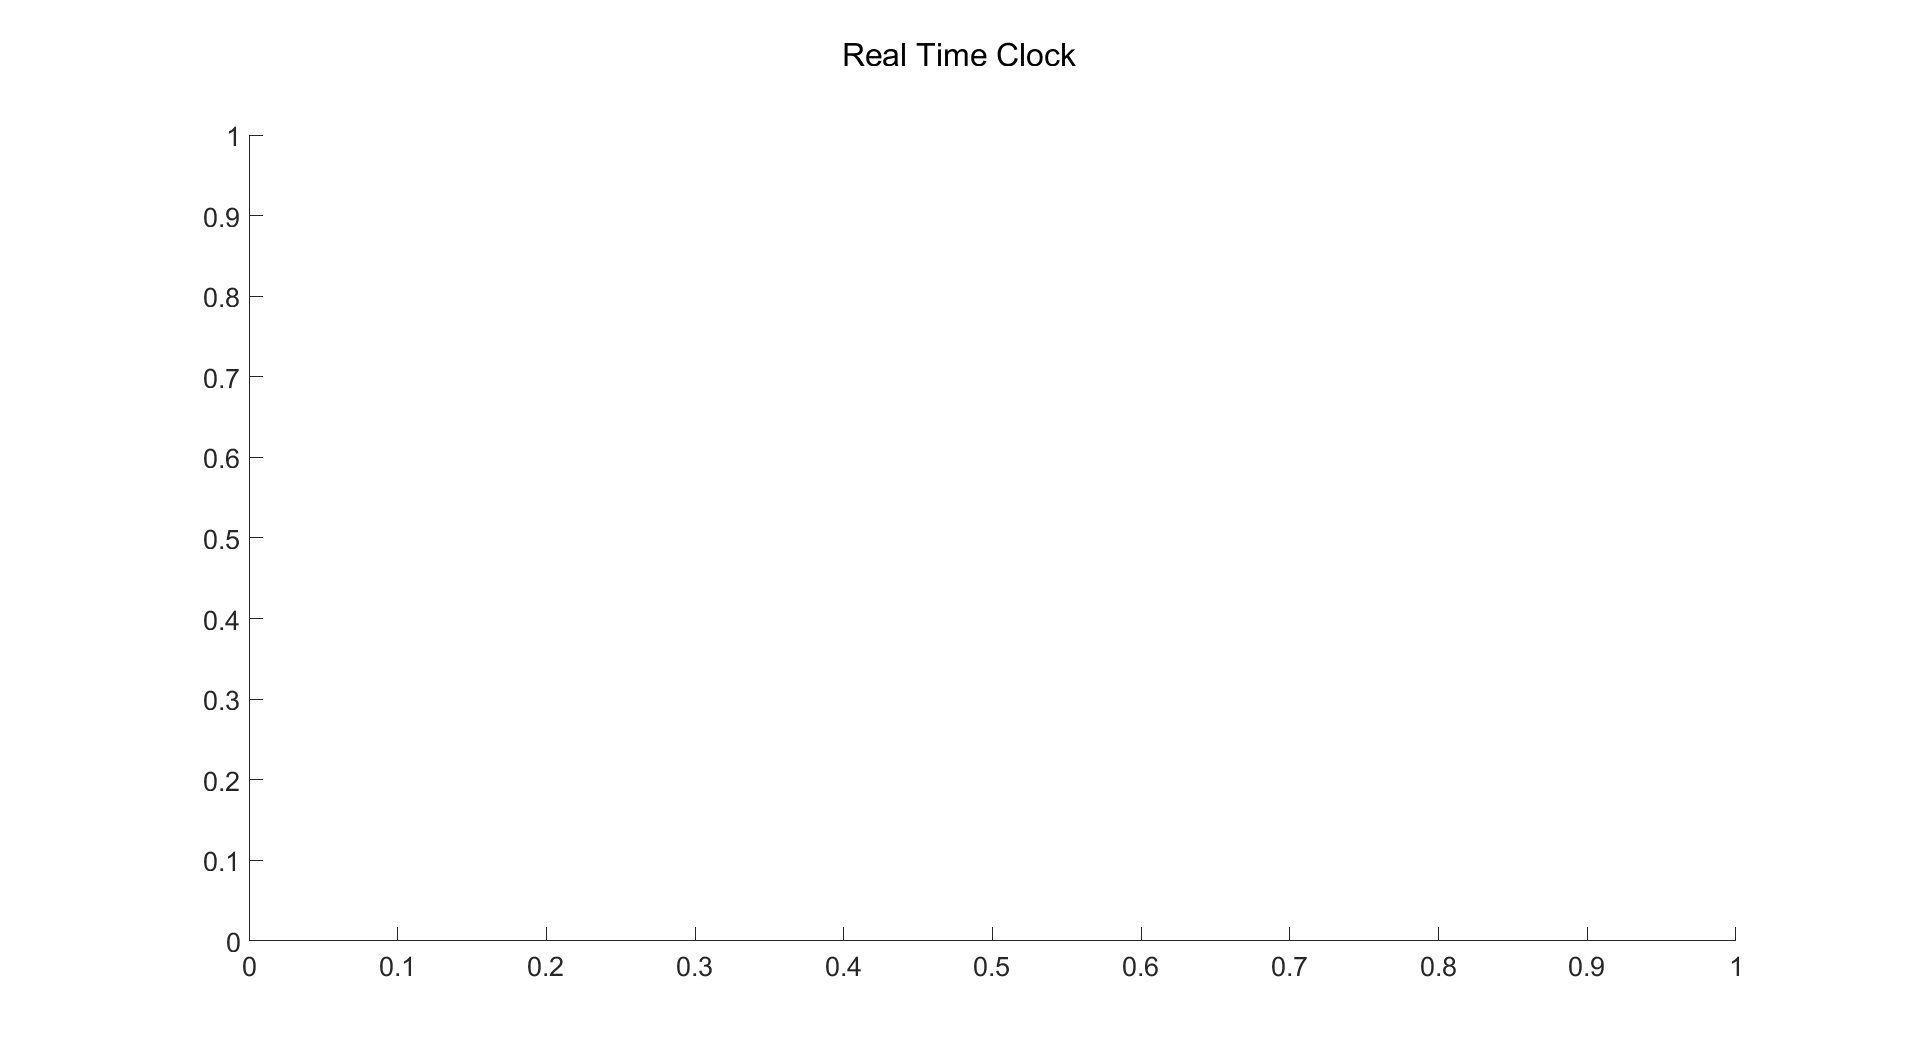

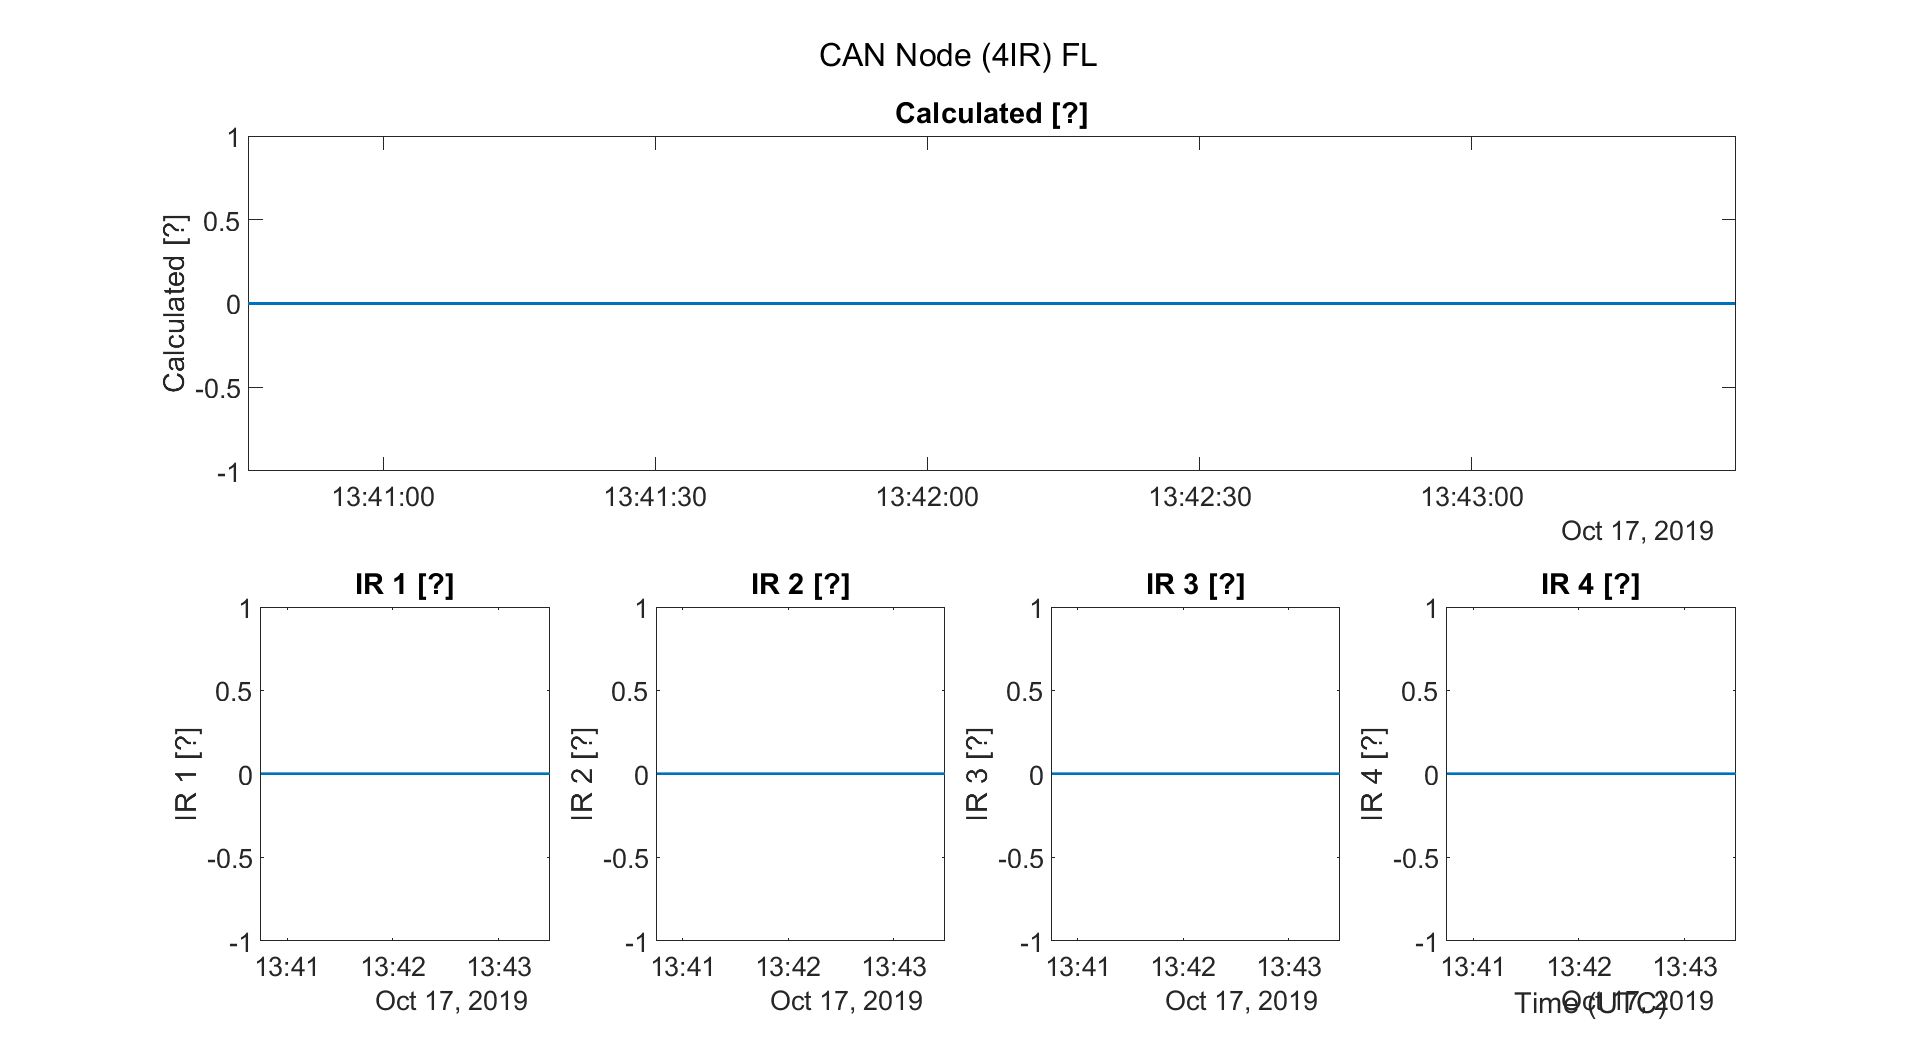

close all;
 
test = exist('id') ;
if  exist('id')
    if  m.list.count(find(m.list.id == id,1)) > 2
        m.plot_all();
    elseif m.list.count < 2
        disp("measurement contains no data")
    else
        disp("ID does not exist in database")
    end
else 
    disp("get first the data")
end

## Own analysis: type your own commands

 
time = (1:size(m.instruments(1,2).data(1,6).values,2))*0.02 + m.start_time;
figure();
fontsize = 20;
set(gca,'fontsize',fontsize) % set fontsize of the plot to 20
set(gcf, 'Position', get(0,'Screensize')); % automatic full screen
set(0, 'DefaultAxesFontSize', fontsize);
plot(time,m.instruments(1,1).data(1,2).values,'LineWidth',2)
ylabel("Turn",'fontsize',fontsize);
ax1 = gca;
yyaxis right
plot(time, m.instruments(1,2).data(1,6).values,'LineWidth',2)
xlabel('Time [s]','fontsize',fontsize);
ylabel("gz",'fontsize',fontsize);
xlim(([min(time) (max(time))]));
title("gz vs turn" ,'fontsize',fontsize);
legend(["turn","gz"]);


### Heatmaps

figure()
heatmap([m.instruments(1,1).data(1,2).values m.instruments(1,2).data(1,6).values])